clc;
clear all; close all;

## Prob 2a. State-space Equation

disp('>> Prob 2a. State-space Equation');

>> Prob 2a. State-space Equation



M = 2.0;
m = 0.1;
l = 0.5;
g = 9.81;

A = [0 1 0 0; ...
    (M+m)*g/M/l 0 0 0; ...
    0 0 0 1; ...
    -m*g/M 0 0 0]

A =          0    1.0000         0         0
   20.6010         0         0         0
         0         0         0    1.0000
   -0.4905         0         0         0


B = [0; -1/M/l; 0; 1/M]

B =          0
   -1.0000
         0
    0.5000



disp(repmat('=',1,80));

## Prob 2b. Stability Analysis

disp('>> Prob 2b. Stability Analysis');

>> Prob 2b. Stability Analysis



eig(A)

ans =          0
         0
    4.5388
   -4.5388



disp(repmat('=',1,80));

## Prob 2c. Controllability Analysis

disp('>> Prob 2c. Controllability Analysis');

>> Prob 2c. Controllability Analysis



rank(ctrb(A,B))

ans = 4


disp(repmat('=',1,80));

## Prob 2d. Full-state Feedback Controller

disp('>> Prob 2d. Full-state Feedback Controller');

>> Prob 2d. Full-state Feedback Controller



P = [-5 -6 -7 -8];
K = acker(A,B,P)

K =  -357.2279  -80.3323 -171.2538 -108.6646


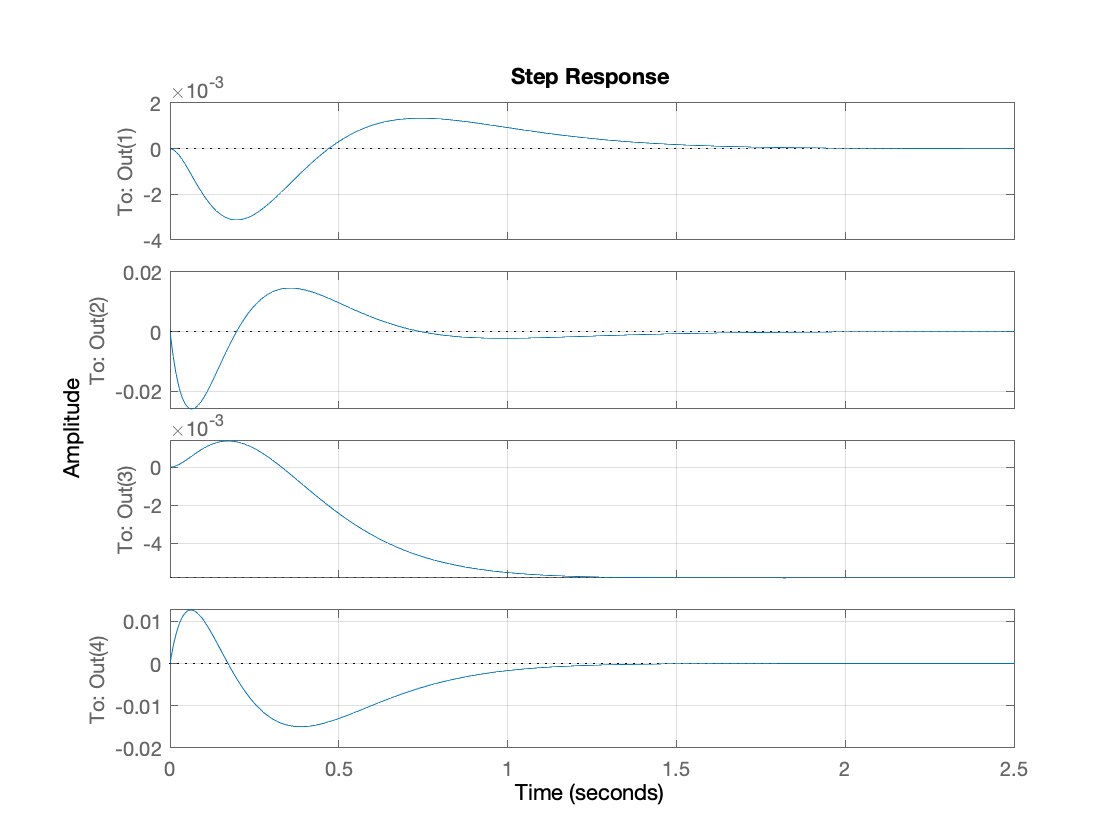


A_cl = A-B*K;
% eig(A_cl)

C = eye(4);
D = 0;
% sys = ss(A,B,C,D);
sys_cl = ss(A_cl,B,C,D);

figure(1)
step(sys_cl); grid on;


disp(repmat('=',1,80));